%CONTROLADOR
k = 100;

%SISTEMA
den = [1 3.5 3.5 1];
G = tf(1, den);

%PLANTA 
G1 = series(G, k);
FTMF = feedback(G1, 1)

FTMF =
 
              100
  ---------------------------
  s^3 + 3.5 s^2 + 3.5 s + 101
 
Continuous-time transfer function.
Model Properties


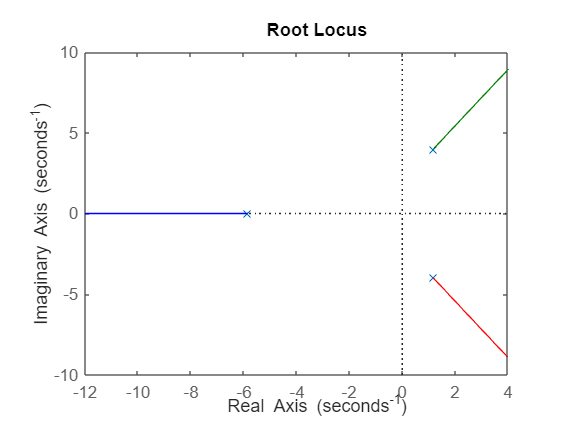

rlocus(FTMF)

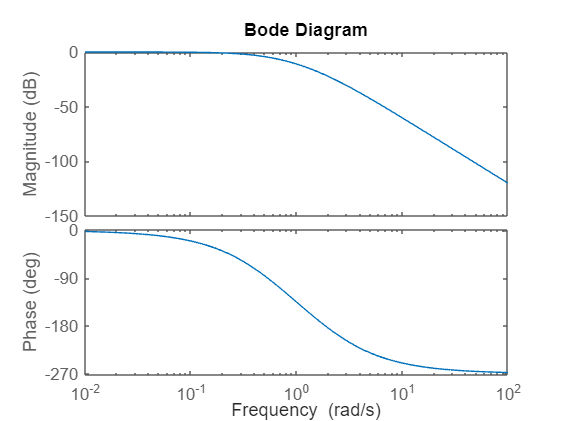


%BODE
bode(G)

w = 2; %frequencia de entrada
[gain, phase] = bode(1, den, w) %valores de ganho e fase

gain = 0.0767

phase = -184.3987

mdB = 20*log10(gain)

mdB = -22.3045


%Espaço de Estados
[A, B, C, D] = tf2ss(1, den)

A =    -3.5000   -3.5000   -1.0000
    1.0000         0         0
         0    1.0000         0


B =      1
     0
     0


C =      0     0     1


D = 0